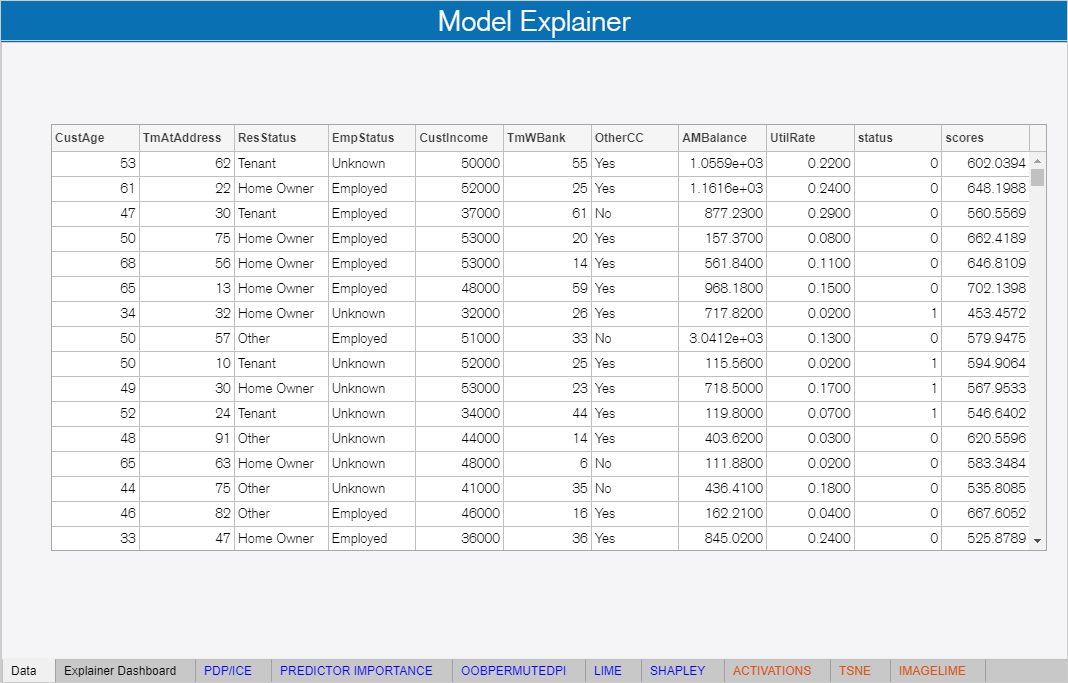

 

addpath(genpath(pwd));
load("myModel.mat")
load("dataTrain.mat")
load("dataNew.mat")
myApp       = ModelExplainerApp();
myModel     = Model("dataTrain", dataTrain, "dataTest", dataNew, "Mdl", trainedModel.RegressionEnsemble);
myView      = View("app", myApp, "model", myModel);
myCallbacks = Callbacks("view", myView);
h           = findobj(myApp.UIFigure, '-property', 'FontName');
arrayfun(@(x) set(x, "FontName", "AkzidenzGrotesk"), h)